# Pitch Detection

The following program processes audio file with single note and detects the pitch along with the harmonics. 

## Loading audio file and plotting 

First, we load init_workspace that consists of two columns, C0 and VarName2, where C0 consists of musical note, and VarName2 consists of corresponding frequency to each note.

load init_workspace

Once init_workspace is loaded, we read the audio file and create a signal. Note that the audio file has two rows, where the top row plots the sound wave heard in left ear, and vice versa. To choose, type either signal(:,1) (left ear) or signal(:,2) (right ear). The time vector is created by dividing the overall length of the signal by the sampling frequeny. 

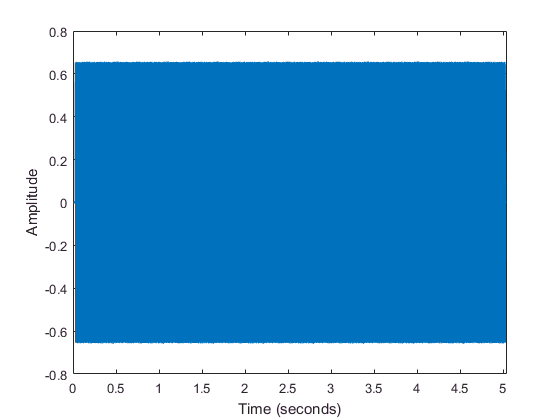

[signal,fs] = audioread('a4.wav'); 
% reads data from the audiofile and returns sampled data, signal, and a
% sample rate of the data, Fs
signal = signal(:,1);
% Because this signal has two separate parts (left & right ears), we will
% sample only one side of the ear (left). To select right, type
% signal(:,2).
t = (0:1/fs:(length(signal)-1)/fs); %creates a time vector that divides the overall time by sample rate fs. 
plot(t,signal); %plots the signal over time)
sound(signal, fs); %plays the sound
xlabel('Time (seconds)')
ylabel('Amplitude')
title('Sound with Unknown Pitch')
xlim([0 t(end)])

%% 
m = length(signal); 
n = pow2(nextpow2(m));%new signal length that is next power of 2 greater than original signal length (for faster computation)
y = fft(signal,n); %Fast fourier transform. Pads the signal with zeros to increase the new signal length n.  
f = (0:n-1)*(fs/n); % frequency vector
power = abs(y/n);   % power spectrum  
power = power(1:n/2+1);
power(2:end-1) = 2*power(2:end-1);

%% 
% The for loop below sets the maximum of x-axis so that the power spectrum
% of the signal truncates the further half of the fft.
for i=1:n
    if f(1,i) >= fs/2
        f = f(1:i);
        maxfreq = i;
        break
    end
end    
vocalrange = f(1:maxfreq); 
vocalpower = power(1:maxfreq);
figure
plot(vocalrange, vocalpower) %Plots the power spectrum over different frequency rate.
xlabel('Frequency')
ylabel('Power')
map = [transpose(vocalrange) vocalpower];

Pitches = [];
Scale = '';
% The for loop selects frequencies with relatively high power and stores it
% inside a matrix Pitches.
for i= 1:length(f)
    if map(i, 2) > 0.002
        Pitches = [Pitches, map(i,1)];
    end
end
% The for loop goes over the frequencies inside the Pitches matrix, and
% determines the closest note to within 1% error. Then, it adds the note
% to a string Scale.
for i = 1:length(Pitches)
    for j = 1:length(VarName2)
        if abs((Pitches(1,i) - VarName2(j,1))/VarName2(j,1)) <= .01
            Scale = Scale + string(C0(j,1) + ' ');
        end
    end
end

%% 
Scale = unique(split(Scale), 'stable');
if Scale(end) == ""
    Scale(end) = [];
end
% After the for loop, the scale string should only consist of the main note
% and the harmonics.
pitch = Scale(1,1); % pitch of the note.

%% 
periodogram(signal, [], [], fs);
spectrogram(signal, 2048, [], [], fs, 'yaxis');colormap;